close all;

font=24;
line_width=2;


## Plotting preasures and flows

### Pressure curves for the Arms

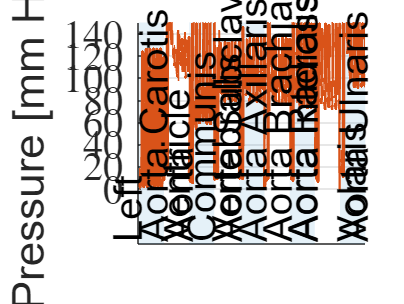

n1=1;%LV
n2=100;%ThA
n3=150;%AbA 
n4=100;% Iliac
n5=180;%FA
n6=250;%Poplitea
n7=250;%Tibialis Anterior
delta=4*1/sample_time;

Pressure=vertcat(out.P_LV.data(n1:n1+delta),out.P_Carot.data(n2:n2+delta),out.P_Vert.data(n2:n2+delta),out.P_SubC.data(n2:n2+delta),out.P_Axi.data(n3:n3+delta),out.P_Brach.data(n4:n4+delta),out.P_Rad.data(n5:n5+delta),out.P_Vola.data(n6:n6+delta),out.P_TibPost.data(n7:n7+delta));

figure;
max_p=150;
time=(out.P_LV.time(2)-out.P_LV.time(1))*(0:length(Pressure)-1);
pos1=[0 0 time(delta) 130];
pos2=[2*time(delta) -50 time(delta) max_p];
pos3=[4*time(delta) -50 time(delta) max_p];
pos4=[6*time(delta) -50 time(delta) max_p];
pos5=[8*time(delta) -50 time(delta) max_p];

p=patch([0 pos1(3) pos1(3) 0],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');hold on;%rectangle('Position',pos1,'FaceColor','#0072BD','EdgeColor','white');
set(p,'FaceAlpha',0.1);
p=patch([pos2(1) pos2(1)+pos2(3) pos2(1)+pos2(3) pos2(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos2);
set(p,'FaceAlpha',0.1);
p=patch([pos3(1) pos3(1)+pos3(3) pos3(1)+pos3(3) pos3(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos3);
set(p,'FaceAlpha',0.1);
p=patch([pos4(1) pos4(1)+pos4(3) pos4(1)+pos4(3) pos4(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos4);
set(p,'FaceAlpha',0.1);
p=patch([pos5(1) pos5(1)+pos5(3) pos5(1)+pos5(3) pos5(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos5);
set(p,'FaceAlpha',0.1);

plot(time,Pressure,'LineWidth',line_width,'Color','#D95319'); hold on; grid on;
ylabel('Pressure [mm Hg]');
% xlabel('time [s]');
axis([0 time(end) -50 max_p]);
set(gca,'FontSize',font);
set(gca, 'XTick', [0]);
set(gca, 'XTickLabel', {' '}, 'TickLabelInterpreter', 'latex');
set(gca, 'YTick', [0 20 40 60 80 100 120 140]);
set(gca, 'YTickLabel', {'0','20','40','60','80','100','120','140'}, 'TickLabelInterpreter', 'latex');

%text
%text
y_txt=-48;

ht=text(pos1(1)+time(delta/2-25), y_txt,{'Left','Ventricle'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos1(1)+time(delta)+time(delta/2), y_txt,{'Aorta Carotis','Communis'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta/2), y_txt,{'Aorta','Vertebralis'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta)+time(delta/2), y_txt,{'Aorta Subclavia'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2), y_txt,'Aorta Axillaris','FontSize',font);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2)+time(delta), y_txt,'Aorta Brachialis','FontSize',font);
set(ht,'Rotation',90);
ht=text(pos4(1)+time(delta/2), y_txt,{'Aorta Radialis'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos4(1)+time(delta/2)+time(delta), y_txt,{'Aorta Interossea','Volaris'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos5(1)+time(delta/2), y_txt,{'Aorta Ulnaris'},'FontSize',font);
set(ht,'Rotation',90);

### Pressure Curves for the Legs

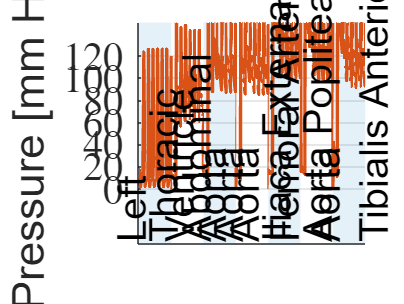

n1=1;%LV
n2=1;%ThA
n3=150;%AbA 
n4=100;% Iliac
n5=180;%FA
n6=250;%Poplitea
n7=250;%Tibialis Anterior
delta=4*1/sample_time;


%LAR-LVE
% exp_LAR_LVE=P_LAR.data(n5)*exp(-1/delta2*log(P_LAR.data(n5)/P_LVE.data(n6))*(0:delta2-1));
% exp_LVE_LSV=P_LVE.data(n6)*exp(-1/delta2*log(P_LVE.data(n6)/P_LSV.data(n7))*(0:delta2-1));
% exp_LSV_FEV=P_LSV.data(n7)*exp(-1/delta2*log(P_LSV.data(n7)/P_FEV.data(n8))*(0:delta2-1));
% exp_FEV_AVC=P_FEV.data(n8)*exp(-1/delta2*log(P_FEV.data(n8)/P_AVC.data(n9))*(0:delta2-1));

Pressure=vertcat(out.P_LV.data(n1:n1+delta),out.P_ThA.data(n2:n2+delta),out.P_AbA.data(n3:n3+delta),out.P_Iliac.data(n4:n4+delta),out.P_FA.data(n5:n5+delta),out.P_Po.data(n6:n6+delta),out.P_TibPost.data(n7:n7+delta));

figure;
time=(out.P_LV.time(2)-out.P_LV.time(1))*(0:length(Pressure)-1);
pos1=[0 0 time(delta) 130];
pos2=[2*time(delta) -50 time(delta) max_p];
pos3=[4*time(delta) -50 time(delta) max_p];
pos4=[6*time(delta) -50 time(delta) max_p];
% pos5=[8*time(delta)-time(70)+3*time(delta) -50 time(delta)+time(delta) 130];
% pos6=[10*time(delta)-time(70)+4*time(delta) -50 time(delta) 120];

p=patch([0 pos1(3) pos1(3) 0],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');hold on;%rectangle('Position',pos1,'FaceColor','#0072BD','EdgeColor','white');
set(p,'FaceAlpha',0.1);
p=patch([pos2(1) pos2(1)+pos2(3) pos2(1)+pos2(3) pos2(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos2);
set(p,'FaceAlpha',0.1);
p=patch([pos3(1) pos3(1)+pos3(3) pos3(1)+pos3(3) pos3(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos3);
set(p,'FaceAlpha',0.1);
p=patch([pos4(1) pos4(1)+pos4(3) pos4(1)+pos4(3) pos4(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos4);
set(p,'FaceAlpha',0.1);
% p=patch([pos5(1) pos5(1)+pos5(3) pos5(1)+pos5(3) pos5(1)],[-50 -50 130 130],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos5);
% set(p,'FaceAlpha',0.1);
% p=patch([pos6(1) pos6(1)+pos6(3)+time(100) pos6(1)+pos6(3)+time(100) pos6(1)],[-50 -50 130 130],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos6);
% set(p,'FaceAlpha',0.1);


plot(time,Pressure,'LineWidth',line_width,'Color','#D95319'); hold on; grid on;
ylabel('Pressure [mm Hg]');
% xlabel('time [s]');
axis([0 time(end) -50 max_p]);
set(gca,'FontSize',font);
set(gca, 'XTick', [0]);
set(gca, 'XTickLabel', {' '}, 'TickLabelInterpreter', 'latex');
set(gca, 'YTick', [0 20 40 60 80 100 120]);
set(gca, 'YTickLabel', {'0','20','40','60','80','100','120'}, 'TickLabelInterpreter', 'latex');

%text
y_txt=-48;
y_txt2=20;
ht=text(pos1(1)+time(delta/2-25), y_txt,{'Left','Ventricle'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos1(1)+time(delta)+time(delta/2), y_txt,{'Thoracic','Aorta'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta/2), y_txt,{'Abdominal','Aorta'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta)+time(delta/2), y_txt,{'Aorta', 'Iliaca Externa'},'FontSize',font);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2), y_txt,'Femoral Artery','FontSize',font);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2)+time(delta), y_txt,'Aorta Poplitea','FontSize',font);
set(ht,'Rotation',90);
ht=text(pos4(1)+time(delta/2), y_txt,{'Aorta','Tibialis Anterior'},'FontSize',font);
set(ht,'Rotation',90);

### Plotting Flow

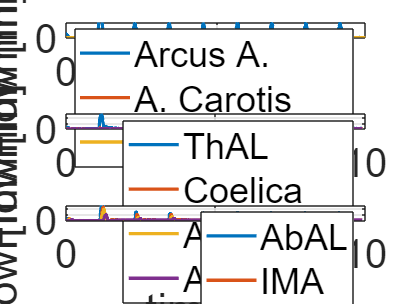


st_point=100;
end_point=10*10^3;
time=(out.F_Arcus.time(2)-out.F_Arcus.time(1))*(0:end_point-st_point);
%setting to zero the negative outputs


%Arms
F_SubC=(out.F_SubC.data(st_point:end_point)+abs(out.F_SubC.data(st_point:end_point)))/2;
F_SubC1=(out.F_SubC1.data(st_point:end_point)+abs(out.F_SubC1.data(st_point:end_point)))/2;
F_Brach=(out.F_Brach.data(st_point:end_point)+abs(out.F_Brach1.data(st_point:end_point)))/2;
F_Brach1=(out.F_Brach1.data(st_point:end_point)+abs(out.F_Brach1.data(st_point:end_point)))/2;
F_Uln=(out.F_Uln.data(st_point:end_point)+abs(out.F_Uln.data(st_point:end_point)))/2;
F_Uln1=(out.F_Uln1.data(st_point:end_point)+abs(out.F_Uln1.data(st_point:end_point)))/2;
F_Anon=(out.F_Anon.data(st_point:end_point)+abs(out.F_Anon.data(st_point:end_point)))/2;
F_Anon1=(out.F_Anon1.data(st_point:end_point)+abs(out.F_Anon1.data(st_point:end_point)))/2;

%center body
F_Arcus=(out.F_Arcus.data(st_point:end_point)+abs(out.F_Arcus.data(st_point:end_point)))/2;
F_Arcus2=(out.F_Arcus2.data(st_point:end_point)+abs(out.F_Arcus2.data(st_point:end_point)))/2;
F_Arcus3=(out.F_Arcus3.data(st_point:end_point)+abs(out.F_Arcus3.data(st_point:end_point)))/2;
F_Arcus4=(out.F_Arcus3.data(st_point:end_point)+abs(out.F_Arcus3.data(st_point:end_point)))/2;
F_Arcus5=F_Arcus-F_Arcus2-F_Arcus3;
F_ThA=(out.F_ThA.data(st_point:end_point)+abs(out.F_ThA.data(st_point:end_point)))/2;

F_ThA1=(out.F_ThA1.data(st_point:end_point)+abs(out.F_ThA1.data(st_point:end_point)))/2;
F_Coel=F_ThA-F_ThA1;
F_Hep=(out.F_Hep.data(st_point:end_point)+abs(out.F_ThA1.data(st_point:end_point)))/2;
F_Lien=(out.F_Lien.data(st_point:end_point)+abs(out.F_Lien.data(st_point:end_point)))/2;
F_AbA=(out.F_AbA.data(st_point:end_point)+abs(out.F_AbA.data(st_point:end_point)))/2;
F_Rena=(out.F_Rena.data(st_point:end_point)+abs(out.F_Rena.data(st_point:end_point)))/2;
F_MesS=(out.F_MesS.data(st_point:end_point)+abs(out.F_MesS.data(st_point:end_point)))/2;
F_Rend=(out.F_Rend.data(st_point:end_point)+abs(out.F_Rend.data(st_point:end_point)))/2;
F_AbA1=(out.F_AbA1.data(st_point:end_point)+abs(out.F_AbA1.data(st_point:end_point)))/2;
F_MesI=(out.F_MesI.data(st_point:end_point)+abs(out.F_MesI.data(st_point:end_point)))/2;

%Legs
F_Legs=(out.F_LegR.data(st_point:end_point)+out.F_LegL.data(st_point:end_point)+abs(out.F_LegL.data(st_point:end_point)+out.F_LegR.data(st_point:end_point)))/2;
F_Fem=(out.F_Fem.data(st_point:end_point)+abs(out.F_Fem.data(st_point:end_point)))/2;
F_Fem1=(out.F_Fem1.data(st_point:end_point)+abs(out.F_Fem1.data(st_point:end_point)))/2;
F_Po=(out.F_Po.data(st_point:end_point)+abs(out.F_Po.data(st_point:end_point)))/2;
F_Po1=(out.F_Po1.data(st_point:end_point)+abs(out.F_Po1.data(st_point:end_point)))/2;

figure;
subplot 311
plot(time,100*F_Arcus,'LineWidth',line_width); hold on; grid on;
plot(time,100*(F_Arcus3-F_Arcus4),'LineWidth',line_width);
plot(time,100*(F_SubC-F_SubC1),'LineWidth',line_width);
ylabel('Flow [ml/min]');
set(gca,'FontSize',font);
legend('Arcus A.','A. Carotis','A. Vertebralis');
axis([0 time(end) 0 50]);

subplot 312
plot(time,100*F_ThA,'LineWidth',line_width); hold on; grid on;
plot(time,100*F_Coel,'LineWidth',line_width);
plot(time,100*F_Lien,'LineWidth',line_width);
plot(time,100*F_Rena,'LineWidth',line_width);
ylabel('Flow [ml/min]');
xlabel('time [s]');
set(gca,'FontSize',font);
legend('ThAL','Coelica','A. Lienalis','A. Renalis');
 
subplot 313
plot(time,100*F_Legs/2,'LineWidth',line_width); hold on; grid on;
plot(time,100*F_Fem,'LineWidth',line_width);
plot(time,100*F_Fem1,'LineWidth',line_width);
plot(time,100*F_Po,'LineWidth',line_width);
ylabel('Flow [ml/min]');
xlabel('time [s]');
set(gca,'FontSize',font);
legend('AbAL','IMA','FA');

## Markov Model

### Computing transition probabilities

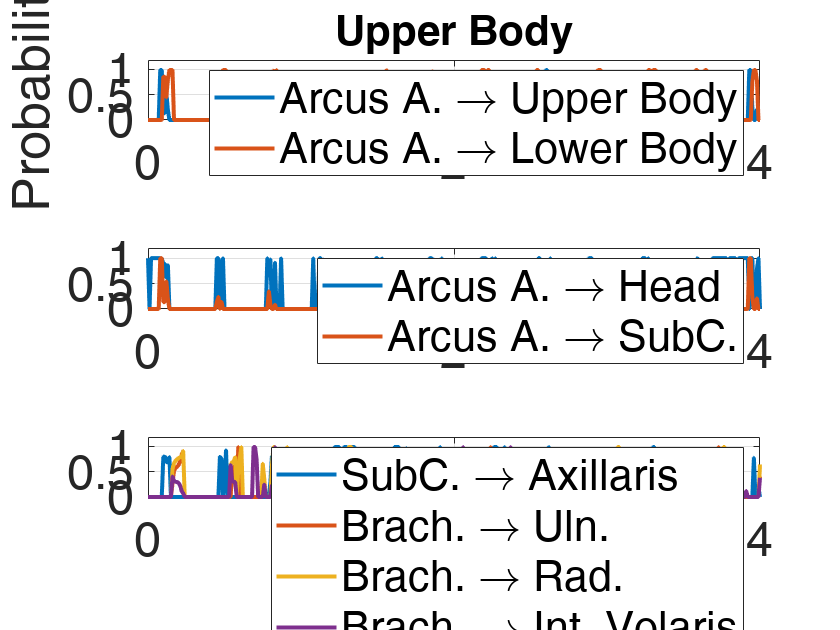


%Upper Body
p_LV_CenterBody=abs(F_Arcus2)./F_Arcus;
%setting to zero negative results
p_LV_CenterBody(find(~F_Arcus))=zeros(1,length(find(~F_Arcus)));
%setting to one larger probabilities
p_LV_CenterBody(find(p_LV_CenterBody>1))=ones(1,length(find(p_LV_CenterBody>1)));
P_LV_UpperBody=1-p_LV_CenterBody;
P_LV_UpperBody(find(~F_Arcus))=zeros(1,length(find(~F_Arcus)));

%Arms
p_LV_SubC=abs(F_Arcus4)./F_Arcus3.*P_LV_UpperBody;
%setting to zero negative results
p_LV_SubC(find(~F_Arcus3))=zeros(1,length(find(~F_Arcus3)));
%setting to one larger probabilities
p_LV_SubC(find(p_LV_SubC>1))=ones(1,length(find(p_LV_SubC>1)));

P_Anon_SubC_d=(F_Anon-F_Anon1)./F_Anon;
%setting to zero negative results and NaN
P_Anon_SubC_d(find(P_Anon_SubC_d<0))=zeros(1,length(find(P_Anon_SubC_d<0)));
P_Anon_SubC_d(find(isnan(P_Anon_SubC_d)))=zeros(1,length(find(isnan(P_Anon_SubC_d))));
%setting to one larger probabilities
P_Anon_SubC_d(find(P_Anon_SubC_d>1))=ones(1,length(find(P_Anon_SubC_d>1)));


%Head
p_LV_Carot_s=1-p_LV_SubC;
p_LV_Carot_s(find(~F_Arcus3))=zeros(1,length(find(~F_Arcus3)));
p_LV_Anon=(F_Arcus3-(F_Arcus-F_Arcus2))./(F_Arcus-F_Arcus2).*P_LV_UpperBody;
%setting to zero negative results and NaN
p_LV_Anon(find(p_LV_Anon<0))=zeros(1,length(find(p_LV_Anon<0)));
p_LV_Anon(find(isnan(p_LV_Anon)))=zeros(1,length(find(isnan(p_LV_Anon))));
%setting to one larger probabilities
p_LV_Anon(find(p_LV_Anon>1))=ones(1,length(find(p_LV_Anon>1)));

p_SubC_Axil=abs(F_SubC1)./F_SubC;
%setting to zero negative results
p_SubC_Axil(find(~F_SubC))=zeros(1,length(find(~F_SubC)));
%setting to one larger probabilities
p_SubC_Axil(find(p_SubC_Axil>1))=ones(1,length(find(p_SubC_Axil>1)));
p_SubC_Vert=1-p_SubC_Axil;
p_SubC_Vert(find(~F_SubC))=zeros(1,length(find(~F_SubC)));

p_Brach_Uln=abs(F_Brach1)./F_Brach;
%setting to zero negative results
p_Brach_Uln(find(~F_Brach))=zeros(1,length(find(~F_Brach)));
%setting to one larger probabilities
p_Brach_Uln(find(p_Brach_Uln>1))=ones(1,length(find(p_Brach_Uln>1)));
p_Brach_Rad=1-p_Brach_Uln;
p_Brach_Rad(find(~F_Brach))=zeros(1,length(find(~F_Brach)));

p_Brach_Uln2=abs(F_Uln1)./F_Uln.*p_Brach_Uln;
%setting to zero negative results
p_Brach_Uln2(find(~F_Uln))=zeros(1,length(find(~F_Uln)));
%setting to one larger probabilities
p_Brach_Uln2(find(p_Brach_Uln2>1))=ones(1,length(find(p_Brach_Uln2>1)));
p_Uln_Volaris=(1-p_Brach_Uln2).*p_Brach_Uln;
p_Uln_Volaris(find(~F_Uln))=zeros(1,length(find(~F_Uln)));

%Upper Body
figure;
subplot 311
plot(time,P_LV_UpperBody,'LineWidth',line_width); hold on; grid on;
plot(time,p_LV_CenterBody,'LineWidth',line_width);
ylabel('Probability');
set(gca,'FontSize',font);
legend('Arcus A. \rightarrow Upper Body','Arcus A. \rightarrow Lower Body');
axis([0 time(end) 0 1.2]);
title('Upper Body','FontSize',font-3);

subplot 312
plot(time,p_LV_Carot_s+p_LV_SubC.*p_SubC_Vert,'LineWidth',line_width); hold on; grid on;
% plot(time,p_SubC_Vert,'LineWidth',line_width);
plot(time,p_LV_SubC,'LineWidth',line_width);
% ylabel('Probability');
set(gca,'FontSize',font);
legend('Arcus A. \rightarrow Head','Arcus A. \rightarrow SubC.');
axis([0 time(end) 0 1.2]);

subplot 313
plot(time,p_SubC_Axil,'LineWidth',line_width); hold on; grid on;
plot(time,p_Brach_Uln2,'LineWidth',line_width);
plot(time,p_Brach_Uln,'LineWidth',line_width);
plot(time,p_Uln_Volaris,'LineWidth',line_width);

% ylabel('Probability');
xlabel('Time [s]')
set(gca,'FontSize',font);
legend('SubC. \rightarrow Axillaris','Brach. \rightarrow Uln.','Brach. \rightarrow Rad.','Brach. \rightarrow Int. Volaris');
axis([0 time(end) 0 1.2]);

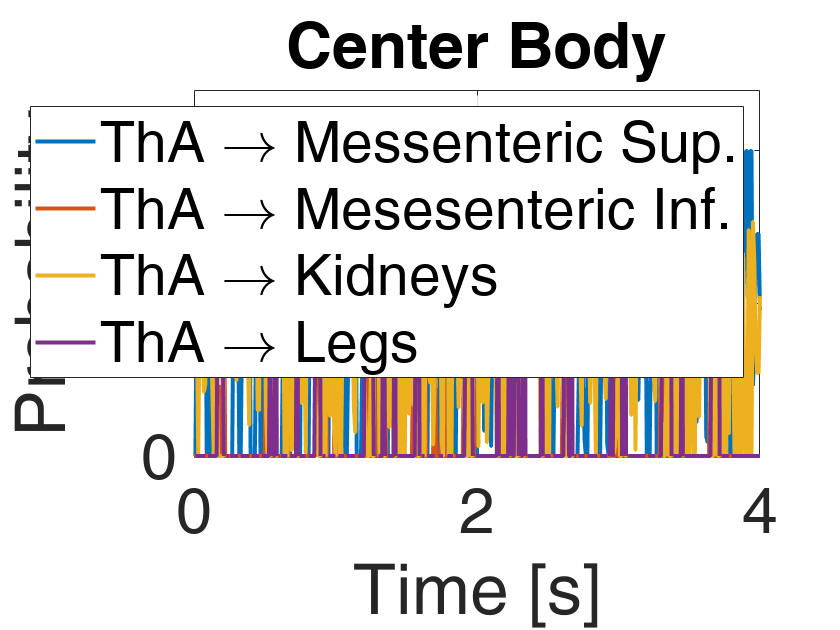


%Center Body
p_ThA_AbA=abs(F_ThA1)./F_ThA.*p_LV_CenterBody;
%setting to zero negative results
p_ThA_AbA(find(~F_ThA))=zeros(1,length(find(~F_ThA)));
%setting to one larger probabilities
p_ThA_AbA(find(p_ThA_AbA>1))=ones(1,length(find(p_ThA_AbA>1)));
p_ThA_Coel=1-p_ThA_AbA;
p_ThA_Coel(find(~F_ThA))=zeros(1,length(find(~F_ThA)));

p_Coel_Hep=abs(F_Hep)./F_Coel;
%setting to zero negative results and NaN
p_Coel_Hep(find(p_Coel_Hep<0))=zeros(1,length(find(p_Coel_Hep<0)));
p_Coel_Hep(find(~F_Coel))=zeros(1,length(find(~F_Coel)));
%setting to one larger probabilities
p_Coel_Hep(find(p_Coel_Hep>1))=ones(1,length(find(p_Coel_Hep>1)));

p_Coel_Lien=abs(F_Lien)./F_Coel;
%setting to zero negative results and NaN
p_Coel_Lien(find(p_Coel_Lien<0))=zeros(1,length(find(p_Coel_Lien<0)));
p_Coel_Lien(find(~F_Coel))=zeros(1,length(find(~F_Coel)));
%setting to one larger probabilities
p_Coel_Lien(find(p_Coel_Lien>1))=ones(1,length(find(p_Coel_Lien>1)));

p_Coel_Gast=1-p_Coel_Hep-p_Coel_Lien;
p_Coel_Gast(find(p_Coel_Gast<0))=zeros(1,length(find(p_Coel_Gast<0)));

p_AbA_MesS=abs(F_MesS)./F_AbA;
%setting to zero negative results
p_AbA_MesS(find(~F_AbA))=zeros(1,length(find(~F_AbA)));
%setting to one larger probabilities
p_AbA_MesS(find(p_AbA_MesS>1))=ones(1,length(find(p_AbA_MesS>1)));

p_AbA_Rend=abs(F_Rend)./F_AbA;
%setting to zero negative results
p_AbA_Rend(find(~F_AbA))=zeros(1,length(find(~F_AbA)));
%setting to one larger probabilities
p_AbA_Rend(find(p_AbA_Rend>1))=ones(1,length(find(p_AbA_Rend>1)));

p_AbA_Rens=abs(F_Rena)./F_AbA;
%setting to zero negative results
p_AbA_Rens(find(~F_AbA))=zeros(1,length(find(~F_AbA)));
%setting to one larger probabilities
p_AbA_Rens(find(p_AbA_Rens>1))=ones(1,length(find(p_AbA_Rens>1)));

p_Kidneys=p_AbA_Rend+p_AbA_Rens;
p_Kidneys(find(p_Kidneys>1))=ones(1,length(find(p_Kidneys>1)));

%Lower Body
p_AbA_Leg_L=1/2*abs(F_Legs)./F_AbA1.*(1-p_AbA_Rend-p_AbA_MesS-p_AbA_Rens);
%setting to zero negative results and NaN
p_AbA_Leg_L(find(~F_AbA1))=zeros(1,length(find(~F_AbA1)));
p_AbA_Leg_L(find(p_AbA_Leg_L<0))=zeros(1,length(find(p_AbA_Leg_L<0)));
%setting to one larger probabilities
p_AbA_Leg_L(find(p_AbA_Leg_L>1))=ones(1,length(find(p_AbA_Leg_L>1)));
p_AbA_MesI=1-2*p_AbA_Leg_L-p_AbA_Rend-p_AbA_MesS-p_AbA_Rens;
%setting to zero negative results
p_AbA_MesI(find(p_AbA_MesI<0))=zeros(1,length(find(p_AbA_MesI<0)));

p_Fem_Po=abs(F_Fem1)./F_Fem;
%setting to zero negative results
p_Fem_Po(find(~F_Fem))=zeros(1,length(find(~F_Fem)));
%setting to one larger probabilities
p_Fem_Po(find(p_Fem_Po>1))=ones(1,length(find(p_Fem_Po>1)));
p_Fem_ProfF=1-p_Fem_Po;
p_Fem_ProfF(find(~F_Fem))=zeros(1,length(find(~F_Fem)));

p_Fem_TibP=abs(F_Po1)./F_Po;
%setting to zero negative results
p_Fem_TibP(find(~F_Po))=zeros(1,length(find(~F_Po)));
%setting to one larger probabilities
p_Fem_TibP(find(p_Fem_TibP>1))=ones(1,length(find(p_Fem_TibP>1)));
p_Fem_TibA=1-p_Fem_TibP;
p_Fem_TibA(find(~F_Po))=zeros(1,length(find(~F_Po)));

figure;
plot(time,p_AbA_MesS,'LineWidth',line_width); hold on; grid on;
plot(time,p_AbA_MesI,'LineWidth',line_width);
plot(time,p_Kidneys,'LineWidth',line_width); 
plot(time,1-p_AbA_MesS-p_AbA_MesI-p_AbA_Rend-p_AbA_Rens,'LineWidth',line_width); 
% plot(time,p_AbA_Rens,'LineWidth',line_width);
ylabel('Probability');
set(gca,'FontSize',font+8);
legend('ThA \rightarrow Messenteric Sup.','ThA \rightarrow Mesesenteric Inf.','ThA \rightarrow Kidneys','ThA \rightarrow Legs');
axis([0 time(end) 0 1.2]);
title('Center Body','FontSize',font+8);
xlabel('Time [s]');

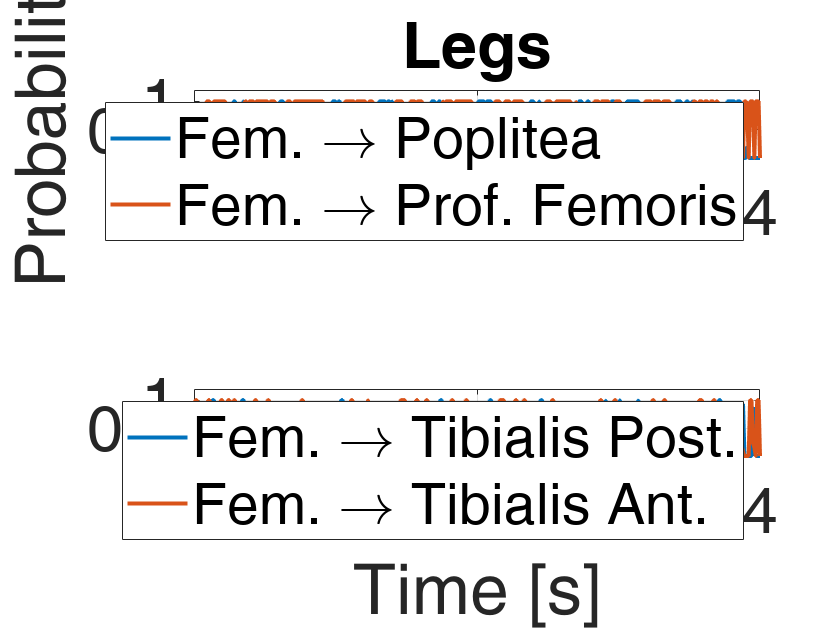


figure;
subplot 211
plot(time,p_Fem_Po,'LineWidth',line_width); hold on; grid on;
plot(time,p_Fem_ProfF,'LineWidth',line_width);
set(gca,'FontSize',font+8);
legend('Fem. \rightarrow Poplitea','Fem. \rightarrow Prof. Femoris');
ylabel('Probability');
axis([0 time(end) 0 1.2]);
title('Legs','FontSize',font+8);

subplot 212
plot(time,p_Fem_TibP,'LineWidth',line_width);hold on; grid on;
plot(time,p_Fem_TibA,'LineWidth',line_width); 
% ylabel('Probability');
set(gca,'FontSize',font+8);
legend('Fem. \rightarrow Tibialis Post.','Fem. \rightarrow Tibialis Ant.');
axis([0 time(end) 0 1.2]);
% ylabel('Probability');
xlabel('Time [s]');

### Transition matrix

PI=zeros(51,51);

%Upper Body
PI(1,2)=1;
PI(2,3)=1;
PI(3,4)=1;
PI(4,5)=1;
PI(26,28)=1

PI =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0  

PI(28,1)=1;
%Head
PI(5,29)=mean(F_Arcus2)/mean(F_Arcus);
PI(5,6)=abs(mean(F_Anon))/mean(F_Arcus);    
PI(5,7)=abs(mean(F_Anon1-F_Anon))/mean(F_Arcus);
PI(5,8)=1-(PI(5,7)+PI(5,6)+PI(5,29));

PI(6,7)=1-mean(F_Anon-F_Anon1)./mean(F_Anon);
PI(8,7)=1-mean(abs(F_SubC1))./mean(F_SubC);
PI(7,26)=PI(6,7); %equal output probability to the input
PI(7,27)=1-PI(6,7);

%Left Arm
PI(8,9)=1-PI(8,7);
PI(9,10)=1;
PI(10,11)=1-mean(F_Brach1)./mean(F_Brach);
PI(10,13)=mean(abs(F_Uln1))./mean(F_Brach);
PI(10,12)=1-PI(10,11)-PI(10,13);
PI(13,14)=1;
PI(12,14)=1;
PI(11,14)=1;
PI(14,15)=1;
PI(15,16)=1;
PI(16,26)=1;
%Right Arm
PI(6,17)=1-PI(6,7);
PI(17,18)=1;
PI(18,19)=1;
PI(19,20)=PI(10,11);
PI(19,21)=PI(10,12);
PI(19,22)=PI(10,13);
PI(22,23)=1;
PI(21,23)=1;
PI(20,23)=1;
PI(23,24)=1;
PI(24,25)=1;
PI(25,27)=1;
PI(27,28)=1;

%Center Body
PI(29,30)=1-mean(F_ThA1)./mean(F_ThA);
PI(29,31)=1-PI(29,30);
PI(30,28)=1;
PI(31,32)=mean(F_MesS)./mean(F_AbA);
PI(32,34)=1;
PI(34,36)=1;
PI(36,37)=1;
PI(37,1)=1;
PI(31,33)=mean(F_MesI)./mean(F_AbA);
PI(33,34)=1;
PI(31,35)=mean(F_Rena+F_Rend)/mean(F_AbA);
PI(31,38)=1/2*(1-PI(31,32)-PI(31,33)-PI(31,35));
PI(31,45)=PI(31,38);
PI(35,36)=1;

%Left Leg
PI(38,39)=1-mean(F_Fem1)./mean(F_Fem);
PI(38,40)=1-PI(38,39);
PI(40,41)=1-mean(F_Po1)./mean(F_Po);
PI(40,42)=1-PI(40,41);
PI(42,43)=1;
PI(41,43)=1;
PI(43,44)=1;
PI(39,44)=1;
PI(44,36)=1;
%Right Leg
PI(45,46)=PI(38,39);
PI(45,47)=PI(38,40);
PI(47,48)=PI(40,41);
PI(47,49)=PI(40,42);
PI(49,50)=1;
PI(41,43)=1;
PI(48,50)=1;
PI(50,51)=1;
PI(46,51)=1;
PI(51,36)=1;

mc = dtmc(PI);
xFix = asymptotics(mc);
%validating
sum(xFix)

#### Computing the probabilities along circuits

%center body
p_Thorax=PI(5,29)*PI(29,30);
p_MesentericaSup=PI(5,29)*PI(29,31)*PI(31,32);
p_MesentericaInf=PI(5,29)*PI(29,31)*PI(31,33);
p_kidneys=PI(5,29)*PI(29,31)*PI(31,35);
%lower body
p_Fem=2*PI(5,29)*PI(29,31)*PI(31,38)*PI(38,39);
p_TibAnt=2*PI(5,29)*PI(29,31)*PI(31,38)*PI(38,40)*PI(40,41);
p_TibPost=2*PI(5,29)*PI(29,31)*PI(31,38)*PI(38,40)*PI(40,42);
%upper body
p_Radialis=2*PI(5,8)*PI(10,11);
p_Volaris=2*PI(5,8)*PI(10,12);
p_Ulnaris=2*PI(5,8)*PI(10,13);
p_Head=1-sum([p_Thorax,p_MesentericaSup,p_MesentericaInf,p_kidneys,p_Fem,p_TibAnt,...
              p_TibPost,p_Radialis,p_Volaris,p_Ulnaris]);


bars=[p_Head,p_Radialis,p_Volaris,p_Ulnaris,p_Thorax,p_MesentericaSup,p_MesentericaInf,...
      p_kidneys,p_Fem,p_TibAnt,p_TibPost];

%validating
sum(bars)

ans = 1.0000

### Traveling time along circuits

load BVS_training_data.mat
bar_time=[mean(delay_Head) mean(delay_Hands) mean(delay_UpperArms) mean(delay_Shoulders) ... %upper body
          mean(delay_Thorax) mean(delay_Liver) mean(delay_Spleen) mean(delay_Kidneys) ... %center body
          mean(delay_Pelvis) mean(delay_Knees) mean(delay_Feet)];

## Plotting the probability for nanosensors to travel along circuits and the traveling time

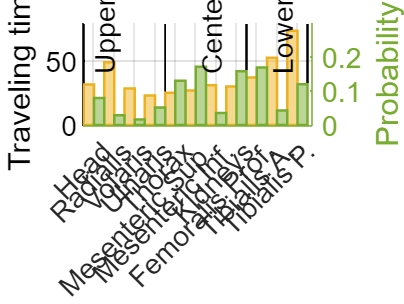

font=17;
font2=17;
y_lim=0.3;
width=0.5;

figure;
%patchs
%Upper body
p=patch([0.5 2*4+0.5 2*4+0.5 0.5],[0 0 80 80],[0.3010 0.7450 0.9330],"EdgeColor",'black','LineWidth',1);hold on;
set(p,'FaceAlpha',0);
%Lower body
p=patch([16.5 22.5 22.5 16.5],[0 0 80 80],[0.3010 0.7450 0.9330],"EdgeColor",'black','LineWidth',1.5);
set(p,'FaceAlpha',0);


%traveling time bars
p=bar(1:2:2*length(bars),bar_time,width,'LineWidth',1.5,'LineStyle','-','FaceColor','#EDB120','EdgeColor','#EDB120'); hold on
set(p,'FaceAlpha',0.5);
ylabel('Traveling time');
set(gca,'FontSize',font,'YColor','#EDB120');


yyaxis right
%probability bars
p=bar((2:2:2*length(bars)),bars,width,'LineWidth',1.5,'LineStyle','-','FaceColor','#77AC30','EdgeColor','#77AC30'); hold off
set(p,'FaceAlpha',0.5);

set(gca, 'XTick', [1.5:2:2*length(bars)]);
set(gca, 'XTickLabel', {'Head','Radialis','Volaris','Ulnaris',...
    'Thorax','Mesenteric Sup.','Mesenteric Inf.','Kidneys',...
    'Femoralis Prof.','Tibialis A.','Tibialis P.'});

%text
y_txt=0.15;
ht=text(2.5, y_txt,{'Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(13, y_txt,{'Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(20, y_txt,{'Lower Body'},'FontSize',font2);
set(ht,'Rotation',90);

grid on;
axis([0.5 2*length(bars)+1 0 0.3]);
set(gca,'FontSize',font,'YColor','#77AC30');
xtickangle(45);
ylabel('Probability');

## Plotting the stationary distribution of nanosensors

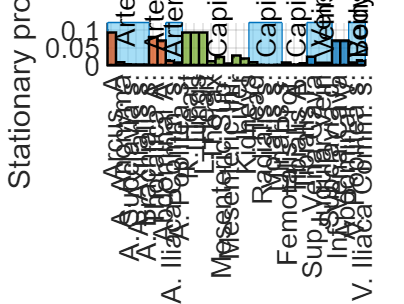

font=17;
font2=17;
width=1;

%static

xFix=xFix_static;

arteries_bar=[ xFix_static(5),xFix_static(6),xFix_static(8),xFix_static(9),xFix_static(10),... %Upper Body
               xFix_static(29),xFix_static(31),... %center body              
               xFix_static(38),xFix_static(40)];%legs
x_artieries=1:length(arteries_bar);
capillaries_bar=[xFix_static(1),xFix_static(2),xFix_static(3),xFix_static(30),xFix_static(32),xFix_static(33),xFix_static(34),xFix_static(35),... %center body
              xFix_static(7),xFix_static(11),xFix_static(12),xFix_static(13),... %arms
              xFix_static(39),xFix_static(41),xFix_static(42)];%legs
x_capillaries=x_artieries(end)+(1:length(capillaries_bar));
veins_bar=[xFix_static(28),xFix_static(26),xFix_static(27),... %Upper body
           xFix_static(37),xFix_static(36),... %center body
           xFix_static(43),xFix_static(44)];%legs
x_veins=x_capillaries(end)+(1:length(veins_bar));



figure;
y_lim=0.12;
%patchs
%arteries center body
p=patch([0.5 5.5 5.5 0.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%arteries legs
p=patch([7.5 9.5 9.5 7.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%capillaries Upper body
p=patch([x_capillaries(1)+7.5 x_capillaries(1)+11.5 x_capillaries(1)+11.5 x_capillaries(1)+7.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%veins Upper body
p=patch([x_veins(1)-.5 x_veins(1)+2.5 x_veins(1)+2.5 x_veins(1)-.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%veins legs
p=patch([x_veins(1)+5-.5 x_veins(end)+.5 x_veins(end)+.5 x_veins(1)+5-.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);

%arteries
h_arteries=bar(x_artieries,arteries_bar,width,'LineWidth',1.5,'LineStyle','--','FaceColor','#D95319','EdgeColor','#000000'); 
set(h_arteries,'FaceAlpha',0.5);
%capillaries
h_capillaries=bar(x_capillaries,capillaries_bar,width,'LineWidth',1.5,'LineStyle','--','FaceColor','#77AC30','EdgeColor','#000000');
set(h_capillaries,'FaceAlpha',0.5);
%veins
h_veins=bar(x_veins,veins_bar,width,'LineWidth',1.5,'LineStyle','--','FaceColor','#0072BD','EdgeColor','#000000'); 
set(h_veins,'FaceAlpha',0.5);

%ytickangle(90);
% new = copyobj(gca,gcf);
% set(new,'YAxisLocation','right');

xFix=xFix_dyn;

arteries_bar=[ xFix_dyn(5),xFix_dyn(6),xFix_dyn(8),xFix_dyn(9),xFix_dyn(10),... %Upper Body
               xFix_dyn(29),xFix_dyn(31),... %center body              
               xFix_dyn(38),xFix_dyn(40)];%legs
x_artieries=1:length(arteries_bar);
capillaries_bar=[xFix_dyn(1),xFix_dyn(2),xFix_dyn(3),xFix_dyn(30),xFix_dyn(32),xFix_dyn(33),xFix_dyn(34),xFix_dyn(35),... %center body
              xFix_dyn(7),xFix_dyn(11),xFix_dyn(12),xFix_dyn(13),... %arms
              xFix_dyn(39),xFix_dyn(41),xFix_dyn(42)];%legs
x_capillaries=x_artieries(end)+(1:length(capillaries_bar));
veins_bar=[xFix_dyn(28),xFix_dyn(26),xFix_dyn(27),... %Upper body
           xFix_dyn(37),xFix_dyn(36),... %center body
           xFix_dyn(43),xFix_dyn(44)];%legs
x_veins=x_capillaries(end)+(1:length(veins_bar));



%arteries
h_arteries=bar(x_artieries,arteries_bar,width,'LineWidth',1.5,'FaceColor','#D95319','EdgeColor','#000000'); 
set(h_arteries,'FaceAlpha',0.5);
%capillaries
h_capillaries=bar(x_capillaries,capillaries_bar,width,'LineWidth',1.5,'FaceColor','#77AC30','EdgeColor','#000000');
set(h_capillaries,'FaceAlpha',0.5);
%veins
h_veins=bar(x_veins,veins_bar,width,'LineWidth',1.5,'FaceColor','#0072BD','EdgeColor','#000000'); 
set(h_veins,'FaceAlpha',0.5);
%text
y_txt=0.04;
ht=text(2.5, y_txt+0.01,{'Arteries Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(6, y_txt,{'Arteries Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(8.2, y_txt-0.02,{'Arteries Legs'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(13.5, y_txt-0.02,{'Capillaries Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(19.5, y_txt-0.02,{'Capillaries Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(23, y_txt-0.02,{'Capillaries Legs'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(26, y_txt+0.01,{'Veins Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(28.5, y_txt-0.02,{'Veins Center','Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(30.5, y_txt-0.02,{'Veins Legs'},'FontSize',font2);
set(ht,'Rotation',90);

set(gca, 'XTick', [1:length(arteries_bar)+length(capillaries_bar)+length(veins_bar)]);
set(gca, 'XTickLabel', {'Arcus. A','A. Anonyma','A. Subclavia s.','A. Axillaris s.','A. Brachialis s.',...
    'Thoratica A.','Abdominal A.','A. Iliaca Comm. s.','A. Poplitea s.'...
    'R. Heart','Lungs','L. Heart','Thorax','Mesenteric Sup.','Mesenteric Inf.','Liver','Kidneys',...
    'Head','Radialis s.','Volaris s.','Ulnaris s.',...
    'Femoralis Prof.','Tibialis A.','Tibialis P.',...
    'Sup. Vena Cava','Jugular Vein','Subclavia d.',...
    'Inf. Vena Cava','Abdominal V.',...
    'V. Poplitea s.','V. Iliaca Comm. s.'});

grid on;
axis([0.5 x_veins(end)+.5 0 y_lim]);
set(gca,'FontSize',font);
xtickangle(90);
ylabel('Stationary probability');